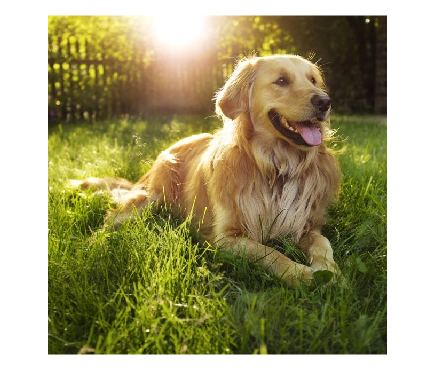

img = imread("squaredog.jpg");
imshow(img);

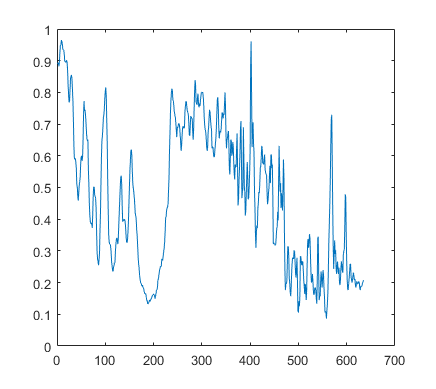


R = im2double(img(:,:,1));
G = im2double(img(:,:,2));
B = im2double(img(:,:,3));

plot(1:635,R(:,1));

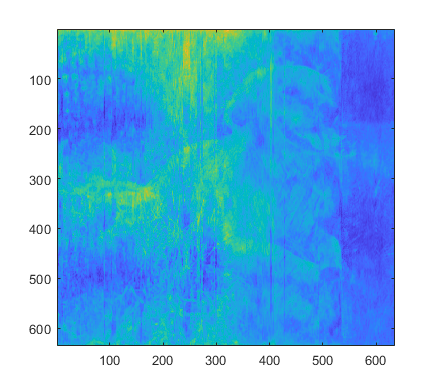


for i =1:635
    RR(:,i) = fft(R(:,i));
end

RR(RR<1) = 0;
%plot(1:size(RR),RR);

%plot(1:size(RR),RR);

for i = 1:635
    RR(:,i) = ifft(RR(:,i));
end

imagesc(RR)


% hold on
% plot(1:635,imag(RR));

%RR = rescale(imag(RR),0,1);


% Rv = rescale(imag(Rv),0,1);
% Gv = rescale(imag(Gv),0,1);
% Bv = rescale(imag(Bv),0,1);

%Ro = rescale(imag(Ro),0,0.5);
%Go = rescale(imag(Go),0,0.5);
%Bo = rescale(imag(Bo),0,0.5);


% outimg = cat(3,Rv.*Ro,Gv.*Go,Bv.*Bo);
% outimg = cat(3,Rv,Gv,Bv);
% outimg = rescale(outimg,0,1);
% imshow(outimg);

